# Task 1 - Single Gaussian

clc
clear all
[training_set, testing_set, vowel_code, talker_group_code, talker_number, vowel_classes] = prepare_data();

## (a) Class means and covariance matrices.

tic
class_means = get_mean(training_set, vowel_code);
class_covariances = get_cov(training_set, vowel_code);
toc

Elapsed time is 0.690939 seconds.


## (b) Classify with full covariance matrix

targets = get_targets(testing_set, vowel_classes);
tic
predicted_classes = map_classifier(testing_set, class_means, class_covariances);
toc

Elapsed time is 46.715018 seconds.


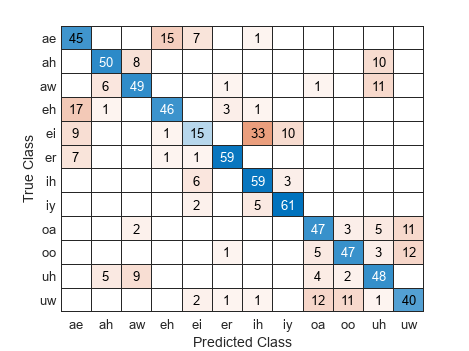

cm = confusionmat(targets, predicted_classes);
confusionchart(cm, string(vowel_classes))
saveas(gca, "figs/confmat_fullcov.png")

%Calculate error rate
error_rate = 1 - (trace(cm) / sum(cm, 'all'))

error_rate = 0.3064

## (c) Classify with diagonal covariance matrix

for i = 1:size(class_covariances, 3)
    class_covariances(:,:,i) = class_covariances(:,:,i).*eye(3);
end
targets = get_targets(testing_set, vowel_classes);
tic
predicted_classes = map_classifier(testing_set, class_means, class_covariances);
toc

Elapsed time is 51.731898 seconds.


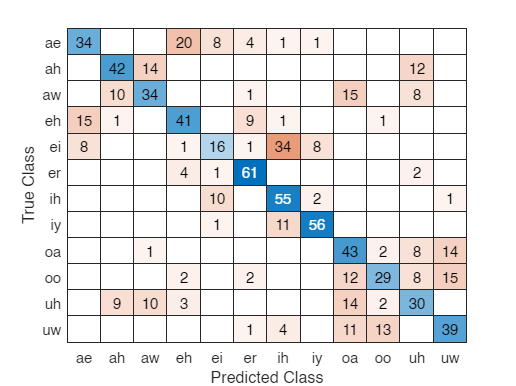

cm = confusionmat(targets, predicted_classes);
confusionchart(cm, string(vowel_classes))
saveas(gca, "figs/confmat_diagcov.png")

error_rate = 1 - (trace(cm) / sum(cm, 'all'))

error_rate = 0.4118